# Signal Analysis for Protocol 2

Water level - 23.4cm

Bottom of Tub - 37cm

Peak Response- 45cm

From the plot with the depths of the amplitudes. The curves oscillate harmonically with increasing amplitude. Higher radar response the deeper the chicken is in the water. Possibility of estimating depth with just the period of the oscillaton.

clc
clear variables
close all
addpath('../functions/');

% Settings
folder = 'chicken_water_19.8cm';
baseline_t = "baseline_zero";
dataType = 'rf';
freq = 3;
dacMIN = 0;
dacMAX = 1400;
global variableName;
variableName = strcat(dataType, num2str(dacMIN), '_', num2str(dacMAX), 'f', num2str(freq));
x = 1:1:1520;


## 1. Plotting the static frequency plot similar to the Protocol 1

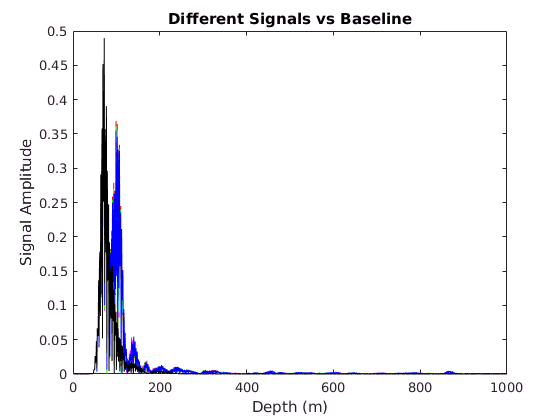

% Plot data
z = 1;
depths = 0:2:48;
for i = depths
   for j = 1:1:1
       filename = strcat("static_D-", num2str(i), "mm_", num2str(j), ".mat");
       static{z, j} = load(strcat(folder, "/", filename), variableName);
   end
   z = z + 1;
end

% Baseline
for j = 1:1:3
    filename = strcat(baseline_t, "_", num2str(j), ".mat");
    baseline{j} = load(strcat(folder, "/", filename), variableName);
end

for j = 1:1
   plot(x, abs(static{1,j}.(variableName)), 'y');
   hold on;
end
for j = 1:1 
   plot(x, abs(static{2,j}.(variableName)), 'm');
end
for j = 1:1 
   plot(x, abs(static{3,j}.(variableName)), 'c');
end
for j = 1:1
   plot(x, abs(static{4,j}.(variableName)), 'r');
end
for j = 1:1 
   plot(x, abs(static{5,j}.(variableName)), 'g');
end
for j = 1:1 
   plot(x, abs(static{6,j}.(variableName)), 'b');
end
for j = 1:1 
   plot(x, abs(baseline{j}.(variableName)), 'k');
end
xlim([0,1000]);
title("Different Signals vs Baseline");
xlabel("Depth (m)");
ylabel("Signal Amplitude");
hold off;

Average of the plots

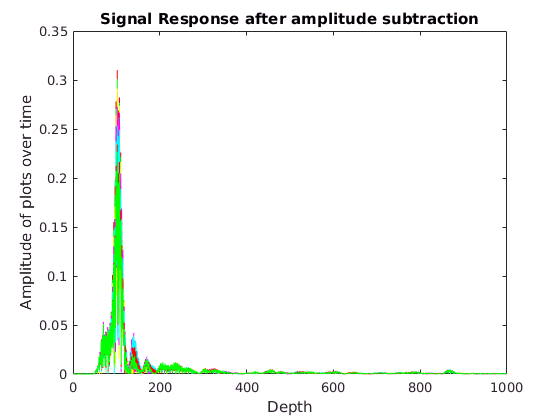

% Baseline average
baseline_avg = 1/3*(baseline{1}.(variableName) ...
    + baseline{2}.(variableName) ...
    + baseline{3}.(variableName));

% Find the average of the plots
z = 1;
for i = depths
%     static_avg(z,:) = (static{z, 1}.(variableName) ...
%         + static{z, 2}.(variableName) ...
%         + static{z, 1}.(variableName))/3;
    static_avg(z,:) = (static{z, 1}.(variableName));
    static_avg(z,:) = static_avg(z,:) - baseline_avg;
    z = z + 1;
end

plot(x, abs(static_avg(1,:)), 'y');
hold on;
plot(x, abs(static_avg(2,:)), 'm');
plot(x, abs(static_avg(3,:)), 'c');
plot(x, abs(static_avg(4,:)), 'r');
plot(x, abs(static_avg(5,:)), 'g');
plot(x, abs(static_avg(6,:)), 'y');
plot(x, abs(static_avg(7,:)), 'm');
plot(x, abs(static_avg(8,:)), 'c');
plot(x, abs(static_avg(9,:)), 'r');
plot(x, abs(static_avg(10,:)), 'g');
xlim([0,1000]);
title('Signal Response after amplitude subtraction');
xlabel('Depth');
ylabel('Amplitude of plots over time');
hold off;

## 3D Visualization

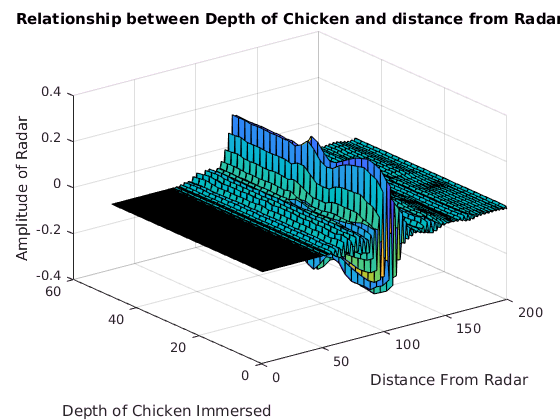

surf(x(1:200), depths, real(static_avg(1:end, 1:200)));
xlabel('Distance From Radar');
ylabel('Depth of Chicken Immersed');
zlabel('Amplitude of Radar');
title('Relationship between Depth of Chicken and distance from Radar');

## Creating an Input Signal

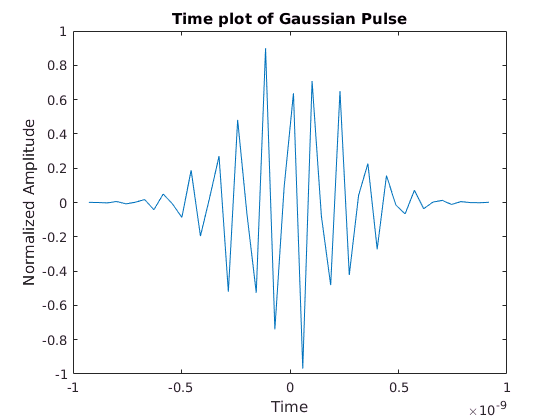

Fs = 23.328e9; % Samples per second
Bw = 1.5e9;

% Using the Xethru Ultra Wideband Pulse
center_freq = 8.748e9;
tc = gauspuls('cutoff',center_freq,Bw/center_freq,[],-60); 
t = -tc : 1/Fs : tc; 
s_tx = gauspuls(t,center_freq,Bw/center_freq); 
figure;
plot(t,s_tx)

title('Time plot of Gaussian Pulse')
xlabel('Time')
ylabel('Normalized Amplitude')

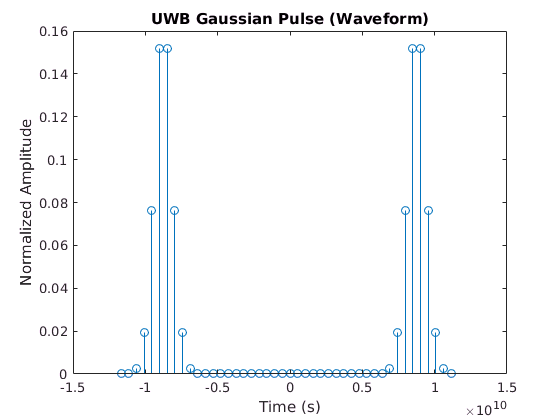


n = length(t);
f = Fs*(-n/2:n/2-1)/n;
S_tx = fftshift(fft(s_tx))/n;
stem(f, abs(S_tx));

title('UWB Gaussian Pulse (Waveform)')
xlabel('Time (s)')
ylabel('Normalized Amplitude')


clear beta fftPulse L P1 P2 pulse tao tc n

## Use the Signal with the matched filter

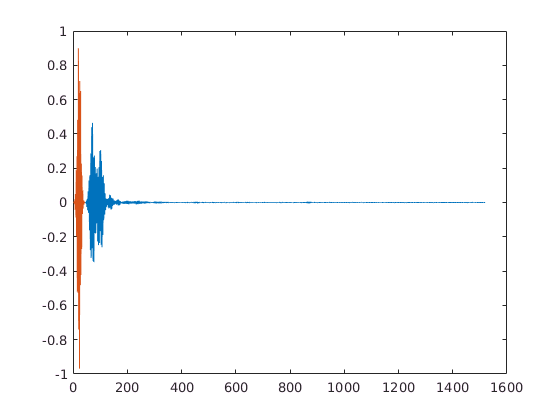

[acor,lag] = xcorr(s_tx,static{1, 1}.(variableName));
plot(static{1, 1}.(variableName));
hold on;
plot(s_tx);

[~,I] = max(abs(acor));
lagDiff = lag(I)

lagDiff = -45

timeDiff = lagDiff/Fs

timeDiff = -1.9290e-09

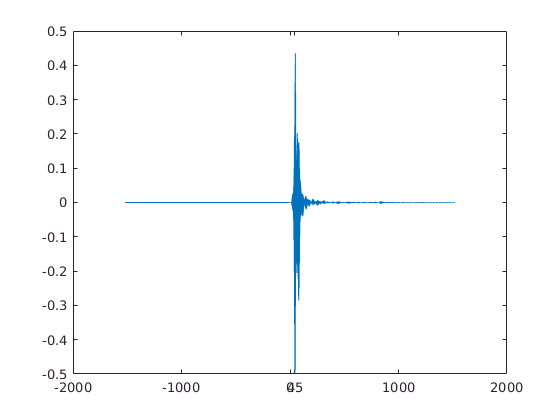


figure
plot(lag,fliplr(acor))
a3 = gca;
a3.XTick = sort([-3000:1000:3000 -lagDiff]);

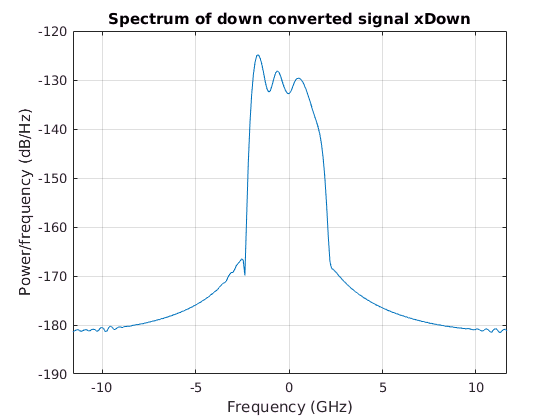


% Downconvert to baseband now
decfactor = 2;
dwnConv = dsp.DigitalDownConverter(...
  'SampleRate',23.328e9,...
  'DecimationFactor',decfactor,...
  'Bandwidth',1.5e9,...
  'PassbandRipple',0.05,...
  'StopbandAttenuation',60,...
  'StopbandFrequencySource', 'Property',...
  'StopbandFrequency',1.5e9,...
  'CenterFrequency',center_freq);

acor = acor(1:3038);
xDown = dwnConv(fliplr(acor)'); % down convert
window = hamming(floor(length(xDown)/10));
figure; pwelch(xDown,window,[],[],Fs,'centered')
title('Spectrum of down converted signal xDown')

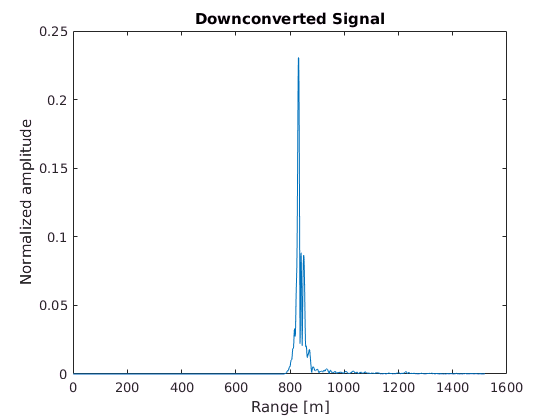


%% Draw signal again
% binLength = (frameStop-frameStart)/(L/decfactor-1);
% rangeVec = ((0:L/decfactor-1)*binLength + frameStart);
ph = plot(abs(xDown).');
title('Downconverted Signal');
ylabel('Normalized amplitude');
xlabel('Range [m]');

## Now do the matched filtering for the entire movement of the chicken

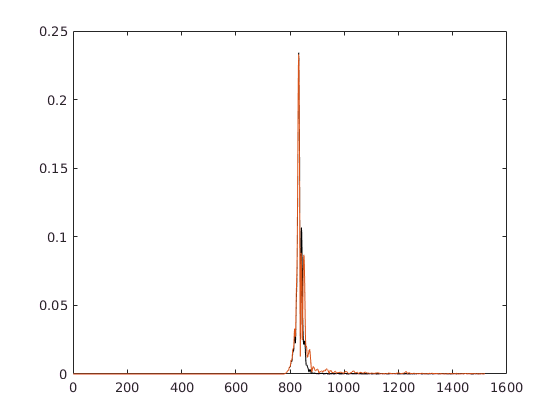

z = 1;
[chicken_matched_baseline, delay] = match_and_downconvert(s_tx, baseline_avg, center_freq);
for i = depths
    chicken_matched(z,:) = match_and_downconvert(s_tx, static{z, 1}.(variableName), center_freq);
    chicken_matched_net(z,:) = chicken_matched(z,:) - chicken_matched_baseline;
    z = z + 1;
end 
plot(abs(chicken_matched_baseline), 'Color', 'black');
hold on;
plot(abs(chicken_matched(1,:)));
hold off;


times = 0:1/Fs:1/Fs*99;
surf(times, -depths, abs(chicken_matched_net(:,length(chicken_matched)/2 + delay:length(chicken_matched)/2+ delay+99)), 'linestyle', 'none');

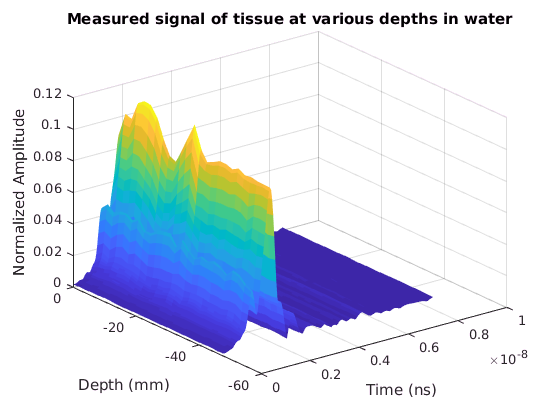

ylabel('Depth (mm)');
xlabel('Time (ns)');
zlabel('Normalized Amplitude');
title('Measured signal of tissue at various depths in water');

## Use the Motion Detection Algorithm